# Projeto 01 - ES020

## 1. Tensões e Deflexões

### 1.1 Momento Fletor - Função de Singularidade

Algo fundamental para o estudo de Resistência de Materiais é a função de singularidade, que nada mais é do que representar, de forma compacta, uma função por partes, como mostrado abaixo:


$$\langle x - y\rangle^n = \begin{cases} 0 & x < y \\ (x - y)^2 & x \ge y\end{cases}$$


Abaixo demonstra-se duas formas diferentes de se programar tal comportamento, utilizando o momento feltor, para $P = M_0 / L$:

base_numbers = number_gen('215663');           % Generate, from RA, the base numbers
[L, Izz, M0] = modeling_data_gen(base_numbers) % Generate, from the Base numbers, the necessary parameters for modeling

L = 63

Izz = 0.3325

M0 = 21000

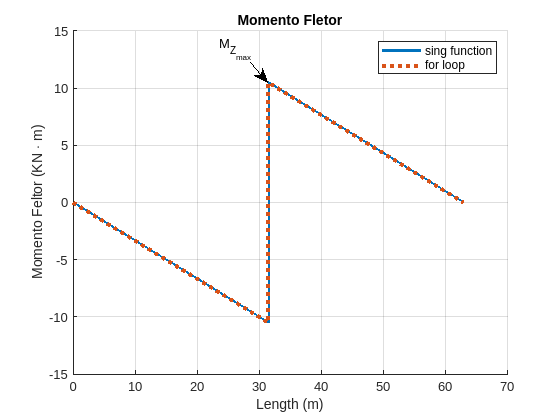


P = M0 ./ L;
X = 0:0.01:L;

% First method, using sing_function
Mz_1 = (P.*L) - M0 - (P.*X) + M0 .* sing_function(X, @(x) x - L./2, 0);

% Second method, using for, if statement
Mz_2 = zeros(size(X)); %Initialize with all zeros

for i = 1:numel(X)
    if (X(i) >= L/2)
        Mz_2(i) = (P.*L) - M0 - (P.*X(i)) + M0;
    else 
        Mz_2(i) = (P.*L) - M0 - (P.*X(i));
    end
end

hold on, grid on;
plot(X, Mz_1 .* 1e-3, LineWidth=2);      % Plot first method, with solid lines
plot(X, Mz_2 .* 1e-3, ":", LineWidth=3); % Plot second method, with dotted lines so we can see both overlapping

title('Momento Fletor');
legend('sing function', 'for loop');
xlabel('Length (m)'), ylabel('Momento Feltor (KN \cdot m)');
annotation(gcf,'textarrow',[0.44765625 0.47734375],[0.851688693098385 0.804698972099853],'String',{'M_{Z_{max}}'});